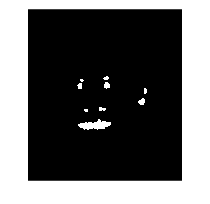

clear
%Problem with: 9
% Read img file
img = imread("../db/DB1/db1_09.jpg");
imshow(img)

% Normalize colors
img_gw = gray_world(img);

% Create facemask 
face_mask = facemask(img_gw);
imshow(face_mask)

%Find eyes and a mouth
eyes = eyemap(img_gw);
eye_mask = eyemask((eyes),face_mask);

imshow(eye_mask)

mouth = mouth_map(img_gw);
mouth_mask = mouthmask(mouth) & face_mask;
imshow(mouth_mask)


[x,y] = mouth_index(mouth_mask)

x = 217.3089

y = 376.4669


[indexX,indexY] = eye_index(eye_mask)

indexX =    82.9856  144.9927  283.1448  358.6510


indexY =   277.1199  229.5865  229.2093  278.0651


mouth_center = [x, y]; % replace with actual coordinates

% Calculate the distance of each eye center from the mouth center
eye_centers = [indexX(:) + indexY(:)/2, indexY(:)];
distances = sqrt(sum((eye_centers - mouth_center).^2, 2));
face_mid = [size(img, 2) / 2, size(img, 1) / 2]; % Mitt av ansiktet
eye_distances_to_mid = sqrt((indexX - face_mid(1)).^2 + (indexY - face_mid(2)).^2);

% Sort eyes based on distance to the middle
[sorted_mid_distances, sorted_mid_indices] = sort(eye_distances_to_mid)

sorted_mid_distances =    59.2664  109.1510  115.1766  166.5167


sorted_mid_indices =      3     4     2     1



% Choose the two closest eyes
% closest_mid_eye_indices = sorted_mid_indices(1:2)
% selected_eyes = [indexX(closest_mid_eye_indices), indexY(closest_mid_eye_indices)];
%----------------------------------------------
 % Initialize variables to store selected eyes
selected_eyes = [];

% Iterate through sorted indices to find the eyes on different sides of the middle
for i = 1:length(sorted_mid_indices)-1
    for j = i+1:length(sorted_mid_indices)
        % Choose the two eyes that are closest to the face's middle
        current_eye_indices = sorted_mid_indices([i, j]);

        % Check if the eyes are on different sides of the face's middle
        if xor(eye_centers(current_eye_indices(1), 1) < mouth_center(1), eye_centers(current_eye_indices(2), 1) < mouth_center(1))
            selected_eyes = current_eye_indices;
            break;  % Break the inner loop when the condition is satisfied
        end
    end
    
    % Break the outer loop when the condition is satisfied
    if ~isempty(selected_eyes)
        break;
    end
end

% Extract the coordinates of the selected eyes
selected_eyes_coordinates = [indexX(selected_eyes(1)), indexY(selected_eyes(1)), ...
                              indexX(selected_eyes(2)), indexY(selected_eyes(2))];

Index exceeds the number of array elements. Index must not exceed 0.


% Visualize the selected eyes
figure;
imshow(img);
hold on;
viscircles(selected_eyes_coordinates(1:2), 10, 'EdgeColor', 'r');
viscircles(selected_eyes_coordinates(3:4), 10, 'EdgeColor', 'r');
plot([selected_eyes_coordinates(1), selected_eyes_coordinates(3)], ...
     [selected_eyes_coordinates(2), selected_eyes_coordinates(4)], ...
     'LineWidth', 2, 'Color', 'r');

% Output the coordinates of the selected eyes
eye1 = selected_eyes_coordinates(1:2);
eye2 = selected_eyes_coordinates(3:4);

%_________________________________________________

viscircles([selected_eyes(1),selected_eyes(3)],10)
viscircles([selected_eyes(2),selected_eyes(4)],10)

% eye1 = [selected_eyes(1),selected_eyes(3)];
% eye2 = [selected_eyes(2),selected_eyes(4)];
% 
% figure;
% imshow(img);
% hold on;
% viscircles([eye1; eye2], 10, 'EdgeColor', 'r');
% plot([eye1(1), eye2(1)], [eye1(2), eye2(2)], 'LineWidth', 2, 'Color', 'r')